[t,x] = ode45(@system_ex,0:1:40,[0,0,1.285]) %use Matlab ode solver: https://www.mathworks.com/help/matlab/ref/ode45.html

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


x =          0         0    1.2850
    2.6659    0.4774    0.6354
    4.9572    0.6495    0.3335
    6.9251    0.6970    0.1915
    8.6173    0.6966    0.1235
   10.0745    0.6803    0.0901
   11.3305    0.6611    0.0731
   12.4138    0.6442    0.0640
   13.3484    0.6311    0.0590
   14.1547    0.6220    0.0561


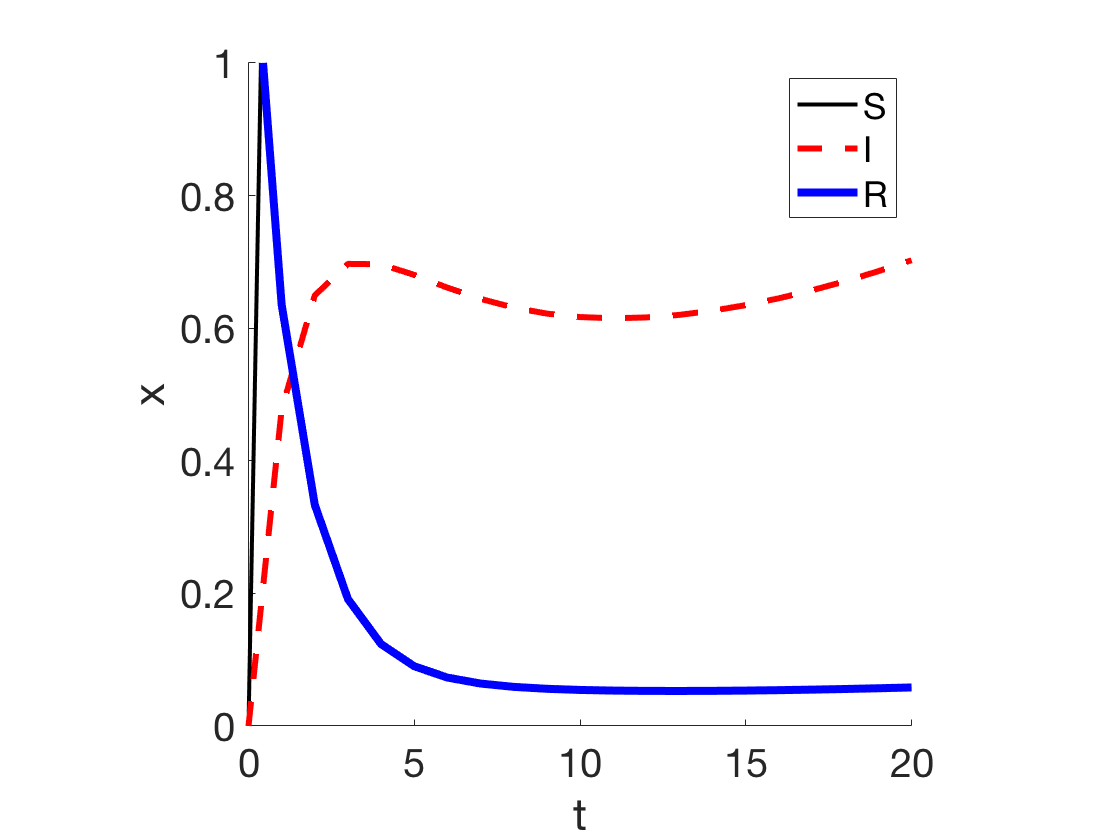

%plot the numerical solutions x_1(t) and x_2(t) vs. t
figure
axes('Fontsize',20)
hold all
axis square

plot(t,x(:,1),'-k','Linewidth',2)
plot(t,x(:,2),'--r','Linewidth',3)
plot(t,x(:,3),'-b','Linewidth',4)
legend('S','I','R')

xlim([0 20])
ylim([0 1])
xlabel('t')
ylabel('x')

Set up a function that computes the right hand side of the system of the first-order DEs

function xprime = system_ex(t, x)
    
lambda = .00659;
b = 0.2;
N = 20;
mu = 0.143;
r = .576; %roe
p = .0619; %phi

 
 
    xprime = zeros(3 ,1);
 
 
    
    xprime(1) = mu*N-((b*x(2)*x(1))/N)+lambda*x(3)-mu*x(1);
    xprime(2) = ((b*x(2)*x(1))/N)+r*x(3)-(p+mu)*x(2);
    xprime(3)= p*x(2)-(r+mu+lambda)*x(3);

  

end

